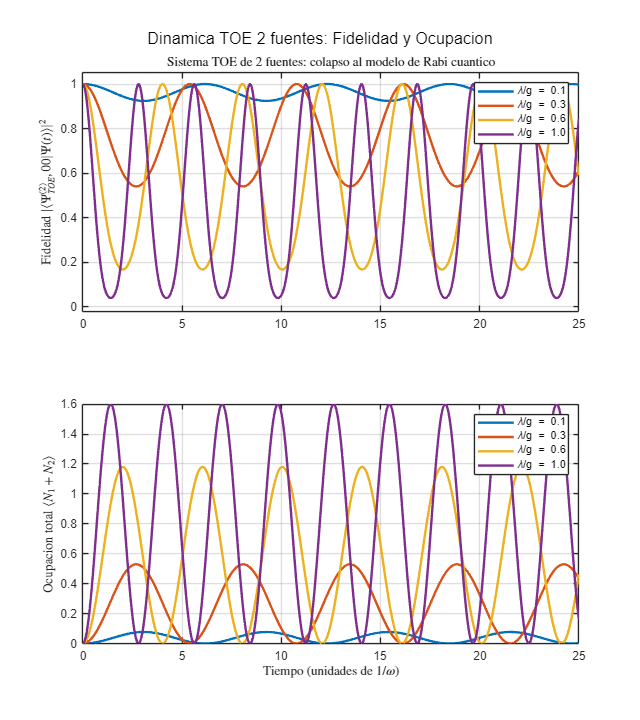

% Graficas de dinamica del modelo TOE de 2 fuentes
%
% 1. Fidelidad y ocupacion total para varios lambda/g
% 2. Barrido de lambda/g: frecuencia de Rabi, comparado con la ley teorica
%

clear; clc; close all;

%% Parametros globales

g = 1.0;
omega0 = 1.0;

%% Funciones auxiliares

function [a, a_dag, N] = osc_ops(n_max)
    dim = n_max + 1;
    a = zeros(dim, dim);
    for n = 1:dim-1
        a(n, n+1) = sqrt(n);
    end
    a_dag = a';
    N = a_dag * a;
end

function H_loc = local_hamiltonian_2f(omega_i, lam, n_max)
    sigma_x = [0, 1; 1, 0];
    I2 = eye(2);
    
    [a, a_dag, N] = osc_ops(n_max);
    I_osc = eye(n_max + 1);
    
    free = omega_i * kron(I2, N + 0.5 * I_osc);
    coupl = lam * kron(sigma_x, a + a_dag);
    
    H_loc = free + coupl;
end

function H = build_H_2f(omega1, omega2, g, lam, n_max)
    sigma_x = [0, 1; 1, 0];
    
    dim_site = 2 * (n_max + 1);
    I_site = eye(dim_site);
    
    L1 = local_hamiltonian_2f(omega1, lam, n_max);
    L2 = local_hamiltonian_2f(omega2, lam, n_max);
    
    H_local = kron(L1, I_site) + kron(I_site, L2);
    
    I_osc = eye(n_max + 1);
    D = kron([0, 1; 1, 0], I_osc);
    
    H_dir = g * kron(D, D);
    
    H = H_local + H_dir;
end

function idx = site_index(dir_idx, n, dim_osc)
    idx = (dir_idx - 1) * dim_osc + n;
end

function idx = full_index(dir1, n1, dir2, n2, dim_osc, dim_site)
    s1 = site_index(dir1, n1, dim_osc);
    s2 = site_index(dir2, n2, dim_osc);
    idx = (s1 - 1) * dim_site + s2;
end

function psi0 = build_psi0(dim_osc, dim_site)
    dim_total = dim_site^2;
    psi0 = zeros(dim_total, 1);
    psi0(full_index(1, 1, 2, 1, dim_osc, dim_site)) = 1 / sqrt(2);
    psi0(full_index(2, 1, 1, 1, dim_osc, dim_site)) = 1 / sqrt(2);
end

function [times, fidelity, N1_t, N2_t] = run_dynamics_2f(g, lam, omega0, t_max, n_steps, psi0, N1_full, N2_full)
    H = build_H_2f(omega0, omega0, g, lam, 1);
    
    times = linspace(0, t_max, n_steps)';
    
    [evecs, D] = eig(H);
    evals = diag(D);
    
    c0 = evecs' * psi0;
    
    fidelity = zeros(n_steps, 1);
    N1_t = zeros(n_steps, 1);
    N2_t = zeros(n_steps, 1);
    
    for it = 1:n_steps
        t = times(it);
        phase = exp(-1i * evals * t);
        psi_t = evecs * (phase .* c0);
        
        fidelity(it) = abs(psi0' * psi_t)^2;
        N1_t(it) = real(psi_t' * (N1_full * psi_t));
        N2_t(it) = real(psi_t' * (N2_full * psi_t));
    end
end

%% Preparacion de operadores y estado inicial

n_max = 1;
dim_osc = n_max + 1;
dim_site = 2 * dim_osc;

[~, ~, N_op] = osc_ops(n_max);
I2_ = eye(2);
N_site = kron(I2_, N_op);
I_site = eye(dim_site);

N1_full = kron(N_site, I_site);
N2_full = kron(I_site, N_site);

psi0 = build_psi0(dim_osc, dim_site);

%% ---------------------------------------------------------------
%% 1. Fidelidad y ocupacion total para varios lambda/g (2 fuentes)
%% ---------------------------------------------------------------

lambdas = [0.1, 0.3, 0.6, 1.0];
t_max = 25.0;
n_steps = 500;

figure('Position', [100, 100, 800, 900]);

colors = lines(length(lambdas));

for i = 1:length(lambdas)
    lam = lambdas(i);
    c = colors(i, :);
    
    [times, F, N1, N2] = run_dynamics_2f(g, lam, omega0, t_max, n_steps, psi0, N1_full, N2_full);
    
    subplot(2, 1, 1);
    plot(times, F, 'Color', c, 'LineWidth', 2, 'DisplayName', sprintf('\\lambda/g = %.1f', lam));
    hold on;
    
    subplot(2, 1, 2);
    plot(times, N1 + N2, 'Color', c, 'LineWidth', 2, 'DisplayName', sprintf('\\lambda/g = %.1f', lam));
    hold on;
end

% Panel superior: Fidelidad
subplot(2, 1, 1);
ylabel('Fidelidad $|\langle\Psi^{(2)}_{TOE},00|\Psi(t)\rangle|^2$', 'Interpreter', 'latex');
title('Sistema TOE de 2 fuentes: colapso al modelo de Rabi cuantico', 'Interpreter', 'latex');
legend('Location', 'northeast');
grid on;
ylim([-0.02, 1.05]);

% Panel inferior: Ocupacion total
subplot(2, 1, 2);
ylabel('Ocupacion total $\langle N_1+N_2\rangle$', 'Interpreter', 'latex');
xlabel('Tiempo (unidades de $1/\omega$)', 'Interpreter', 'latex');
legend('Location', 'northeast');
grid on;

sgtitle('Dinamica TOE 2 fuentes: Fidelidad y Ocupacion');

% Ruta de guardado en el escritorio
desktop_path = fullfile(getenv('USERPROFILE'), 'Desktop');
if isempty(getenv('USERPROFILE'))
    % Fallback para sistemas no-Windows
    desktop_path = fullfile(getenv('HOME'), 'Desktop');
end

filename1 = fullfile(desktop_path, 'toe_2f_fidelity_occupation.png');
saveas(gcf, filename1, 'png');

fprintf('Guardado: %s\n\n', filename1);

Guardado: C:\Users\Usuario\Desktop\toe_2f_fidelity_occupation.png



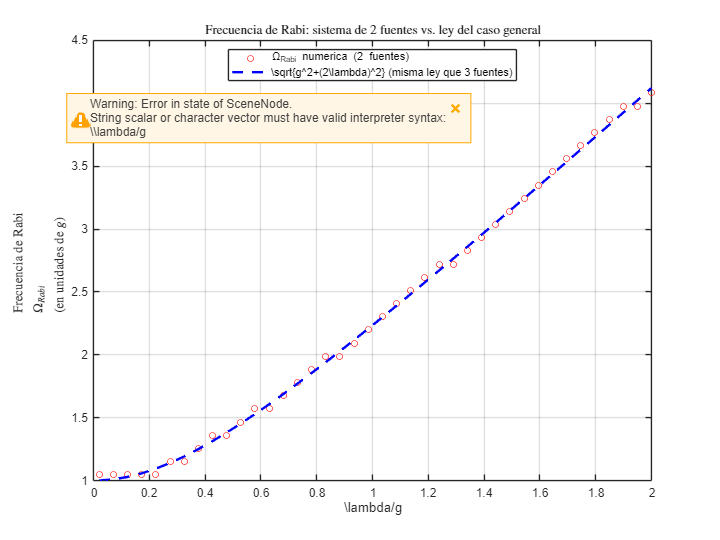

Guardado: C:\Users\Usuario\Desktop\toe_2f_rabi_frequency.png




%% ---------------------------------------------------------------
%% 2. Barrido de lambda/g: frecuencia de Rabi
%% ---------------------------------------------------------------

lambdas_sweep = linspace(0.02, 2.0, 40);
t_max2 = 60.0;
n_steps2 = 4000;
dt = t_max2 / (n_steps2 - 1);

rabi_2f = zeros(size(lambdas_sweep));

for i = 1:length(lambdas_sweep)
    lam = lambdas_sweep(i);
    
    [times, F, N1, N2] = run_dynamics_2f(g, lam, omega0, t_max2, n_steps2, psi0, N1_full, N2_full);
    
    % FFT de la parte oscilante de la fidelidad
    F_ac = F - mean(F);
    spectrum = abs(fft(F_ac));
    spectrum = spectrum(1:floor(length(spectrum)/2)+1);  % solo frecuencia positiva
    
    freqs = (0:length(spectrum)-1) * (1 / (n_steps2 * dt)) * 2 * pi;
    
    % Buscar pico principal (excluyendo DC)
    [~, idx_peak] = max(spectrum(2:end));
    idx_peak = idx_peak + 1;
    
    rabi_2f(i) = freqs(idx_peak);
end

% Grafica de frecuencia de Rabi
figure('Position', [100, 100, 800, 600]);

plot(lambdas_sweep, rabi_2f, 'o', 'Color', 'red', 'MarkerSize', 5, ...
    'DisplayName', '\Omega_{Rabi} numerica (2 fuentes)');
hold on;

% Ley teorica: sqrt(g^2 + (2*lambda)^2)
plot(lambdas_sweep, sqrt(g^2 + (2*lambdas_sweep).^2), '--', 'Color', 'blue', 'LineWidth', 2, ...
    'DisplayName', '\sqrt{g^2+(2\lambda)^2} (misma ley que 3 fuentes)');

xlabel('\lambda/g', 'Interpreter', 'latex');
ylabel('Frecuencia de Rabi $\Omega_{Rabi}$ (en unidades de $g$)', 'Interpreter', 'latex');
title('Frecuencia de Rabi: sistema de 2 fuentes vs. ley del caso general', 'Interpreter', 'latex');
legend('Location', 'best');
grid on;

filename2 = fullfile(desktop_path, 'toe_2f_rabi_frequency.png');
saveas(gcf, filename2, 'png');

%% Tabla de comparacion numerica vs teorica

fprintf('lambda/g | Omega_Rabi (2 fuentes) | sqrt(g^2+(2*lam)^2)\n');

lambda/g | Omega_Rabi (2 fuentes) | sqrt(g^2+(2*lam)^2)


fprintf('------------------------------------------------------\n');

------------------------------------------------------


step = 4;
for i = 1:step:length(lambdas_sweep)
    lam = lambdas_sweep(i);
    om = rabi_2f(i);
    om_teo = sqrt(g^2 + (2*lam)^2);
    fprintf('%.3f   |  %.4f  |  %.4f\n', lam, om, om_teo);
end

0.020   |  1.0469  |  1.0008
0.223   |  1.0469  |  1.0950
0.426   |  1.3610  |  1.3139
0.629   |  1.5704  |  1.6074
0.832   |  1.9892  |  1.9419
1.035   |  2.3033  |  2.2996
1.238   |  2.7220  |  2.6712
1.442   |  3.0361  |  3.0516
1.645   |  3.4549  |  3.4379
1.848   |  3.8737  |  3.8283
